## **Simple example**

clear all
close all
ub = [1 ; 1];
lb = [-1; -1];
Aeq = [];
beq = [];
f = [1 1];
x = linprog(f,[],[],Aeq,beq,lb,ub)

Optimal solution found.



x =     -1
    -1


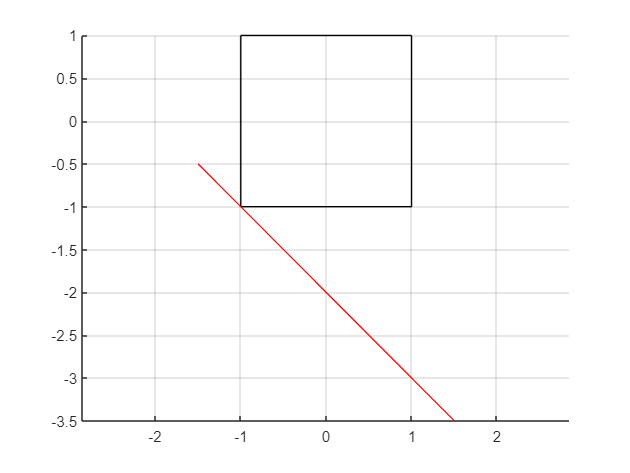

figure()
rectangle('Position',[-1 -1 2 2])
xx = -1.5:0.1:1.5;
fun_line = @(a,x,x0) -a(1)/a(2) * x + a * x0 / a(2);
yy = fun_line(f,xx,x);
hold on
plot(xx,yy,'-r')
axis equal
grid on

## Chebyushev poligonal center - LP like problem

A = [ 1 1;
      -1 -1;
      1 -1;
      -1 1 ];
b = [1; 2; 1; 1];
f = [0 0 -1]

f =      0     0    -1


A = [A, norm([1 1])*ones(4,1)]

A =     1.0000    1.0000    1.4142
   -1.0000   -1.0000    1.4142
    1.0000   -1.0000    1.4142
   -1.0000    1.0000    1.4142


x = linprog(f,A,b,[],[],[],[])

Optimal solution found.



x =          0
         0
    0.7071


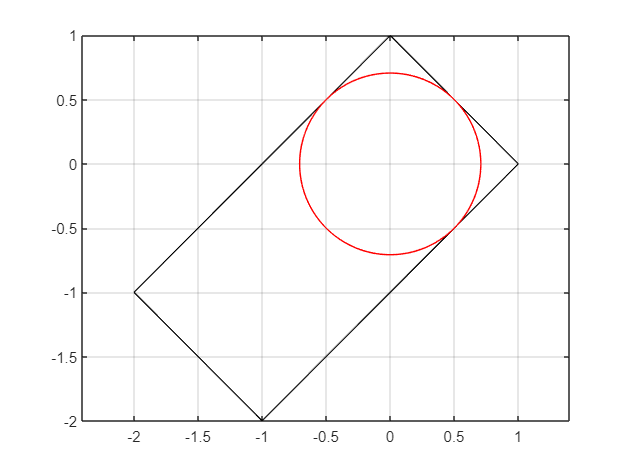

figure()
plot([0 1 -1 -2 0],[1 0 -2 -1 1],'k')
axis equal
grid on
hold on
ang=0:0.01:2*pi; 
xp=x(3)*cos(ang);
yp=x(3)*sin(ang);
plot(x(1)+xp,x(2)+yp,'-r');

## **SDP problems**

A = [ 1 1;
      -1 -1;
      1 -1;
      -1 1 ];
b = [1; 2; 1; 1];
X_asterisk = inv(A'*A)*A'*b

X_asterisk =    -0.2500
   -0.2500



quadprog(2*A' * A, -2 * b' * A)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =    -0.2500
   -0.2500


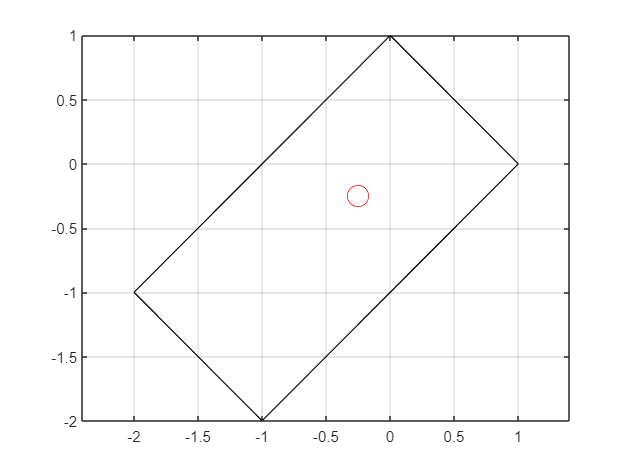

figure()
plot([0 1 -1 -2 0],[1 0 -2 -1 1],'k')
hold on
grid on
scatter(ans(1),ans(2),200,"red")
axis equal

t = sdpvar(1,1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1


X = sdpvar(2,1)

Linear matrix variable 2x1 (full, real, 2 variables)
Coeffiecient range: 1 to 1


% Another style
% sdpvar t(1,1,real) X(2,1,'real')
F = [eye(4), A*X - b;
     (A*X - b)', t];
h = t;
opt = sdpsettings('solver','sdpt3','sdpt3.steptol',1e-12, 'sdpt3.gaptol',1e-13);
optimize([F >= 0],t,[]);


 num. of constraints =  3
 dim. of sdp    var  =  5,   num. of sdp  blk  =  1
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.5e+00|4.0e+00|5.0e+02| 4.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.6e-06|4.3e-02|3.1e+01| 1.947790e+01 -8.653472e+00| 0:0:00| chol  1  1 
 2|0.993|0.996|4.9e-08|4.4e-03|3.8e-01|-6.154155e+00 -6.454311e+00| 0:0:00| chol  1  1 
 3|0.983|1.000|2.2e-08|4.3e-04|6.6e-03|-6.493976e+00 -6.493043e+00| 0:0:00| chol  1  1 
 4|0.974|1.000|7.1e-08|4.3e-05|1.8e-04|-

value(X)

ans =    -0.2500
   -0.2500


figure()
plot([0 1 -1 -2 0],[1 0 -2 -1 1],'k')
hold on
grid on
scatter(ans(1),ans(2),200,"red")
axis equal